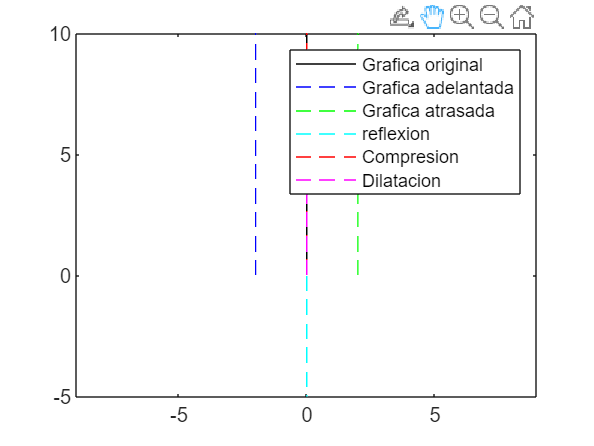

% Crear un vector de tiempo
t = 0:0.01:10;

% Crear la función delta de Dirac 
delta = zeros(size(t));
delta(t == 0) = Inf;

% Graficas 
figure;
title('Función Delta de Dirac');
xlabel('Tiempo');
ylabel('\delta(t)');

grid on;

% Grafica de grafica orginal
plot(delta, t, "k", 'DisplayName', 'Grafica original');
hold on;

% Graficar adelantada
plot(delta - 2, t, "--b", 'DisplayName', 'Grafica adelantada');

% Graficar atrasada
plot(delta + 2, t, "--g", 'DisplayName', 'Grafica atrasada');

% Graficar reflexion
plot(delta, -t, "--c", 'DisplayName', 'reflexion');

% Graficar Compresion
plot(delta, t*2, "--r", 'DisplayName', 'Compresion');

% Graficar Compresion
plot(delta, t/2, "--m", 'DisplayName', 'Dilatacion');
axis([-9 9 -5 10]);
legend;